# 2RC_fitting_based on plus

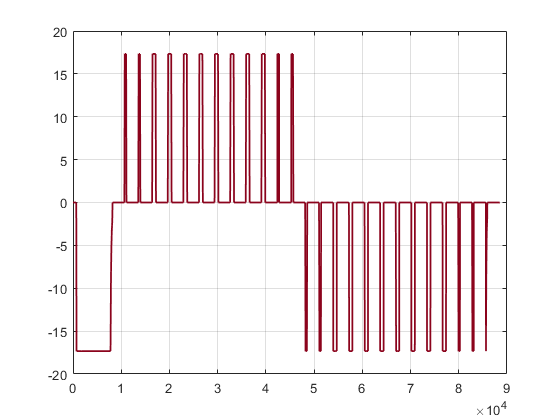

% 2021.12.06 用于2RC基于脉冲放电OCV实验下的参数辨识
close all
clear
clc

load('Data.mat');
R0fittime = 1; % 单位s 设定的直流内阻响应时间
taufittime = (180)/5; % 单位 采样点个数 设定的时间常数拟合弛豫时间
theta_d = zeros(5,11);
theta_c = zeros(5,11);
polarU1 = zeros(1,11); 
polarU2 = zeros(1,11);

k = 1; 
for index = 1:length(I)-1
    if (abs(I(index)) < 0.01 && abs(I(index+1)) >0.01 )
        RTC(k) = index;                                     % Rest to charge num index
        k = k+1;                                            
    end
end
RTC(end+1) = length(I);

k = 1;
for index = 1:length(I)-1
    if (abs(I(index)) > 0.01 && abs(I(index+1)) <0.01 )
        CTR(k) = index;                                     % Charge to Rest num index
        k = k+1;
    end
end

plot(I,'color',[140,3,28]/256,'LineWidth',1.3);
grid on;

## 欧姆拟合

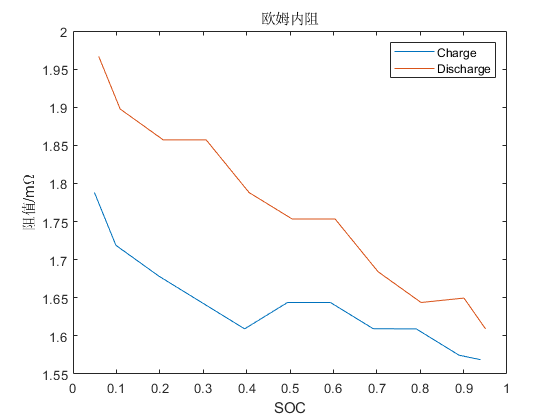

% 放电
R0_d = zeros(1,11); % 初始化

for i = 3:13
    R0_d(i-2) = abs((Ut(RTC(i)-2) - Ut(RTC(i)+R0fittime))/(I(RTC(i))-I(RTC(i)+R0fittime))); % -2防止错误采样
end

R0_d = fliplr(R0_d);
soctable_d = fliplr(refsoc(RTC(3:13))');

% 充电

R0_c = zeros(1,11);

for i = 15:25
    R0_c(i-14) = abs((Ut(RTC(i)-2) - Ut(RTC(i)+R0fittime))/(I(RTC(i))-I(RTC(i)+R0fittime))); % -2防止错误采样
end

soctable_c = refsoc(RTC(15:25))';

figure,plot(soctable_c,R0_c*1000), hold on ,plot(soctable_d,R0_d*1000);
hold off;
legend('Charge','Discharge');
title('欧姆内阻');
xlabel('SOC'),ylabel('阻值/m\Omega');


theta_d(1,:) = R0_d; % 整理参数表
theta_c(1,:) = R0_c;

## 放电部

% ***************************************************************************************************

## 时间常数

cfun =      General model:
     cfun(t) = a-b*exp(-c*t)-d*exp(-e*t)
     Coefficients (with 95% confidence bounds):
       a =       3.181  (3.159, 3.202)
       b =      0.0376  (0.03131, 0.0439)
       c =     0.05508  (0.04501, 0.06516)
       d =     0.04751  (0.03211, 0.06292)
       e =    0.005181  (0.0007455, 0.009617)

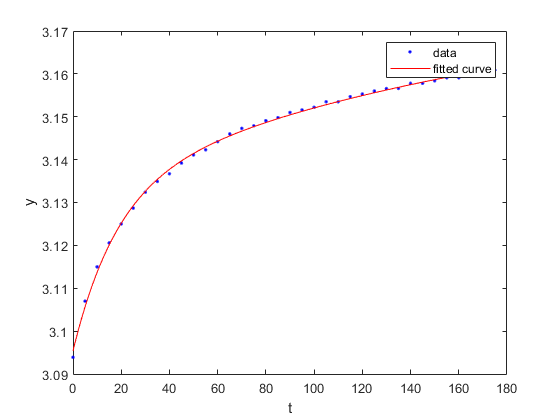

cfun =      General model:
     cfun(t) = a-b*exp(-c*t)-d*exp(-e*t)
     Coefficients (with 95% confidence bounds):
       a =       3.188  (3.187, 3.188)
       b =     0.01722  (0.01509, 0.01935)
       c =     0.09464  (0.08013, 0.1092)
       d =     0.03111  (0.02951, 0.0327)
       e =     0.01513  (0.01347, 0.01679)

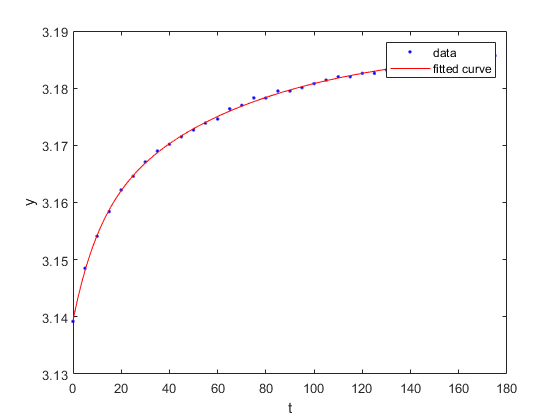

cfun =      General model:
     cfun(t) = a-b*exp(-c*t)-d*exp(-e*t)
     Coefficients (with 95% confidence bounds):
       a =       3.232  (3.231, 3.233)
       b =     0.02509  (0.02425, 0.02594)
       c =     0.01195  (0.01039, 0.0135)
       d =     0.01267  (0.01117, 0.01418)
       e =     0.08829  (0.07467, 0.1019)

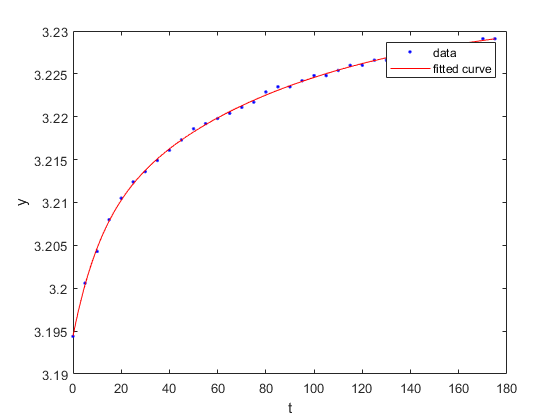

cfun =      General model:
     cfun(t) = a-b*exp(-c*t)-d*exp(-e*t)
     Coefficients (with 95% confidence bounds):
       a =        3.26  (3.258, 3.262)
       b =     0.02423  (0.02326, 0.0252)
       c =    0.009565  (0.007095, 0.01203)
       d =     0.01198  (0.009754, 0.01421)
       e =     0.07572  (0.05832, 0.09312)

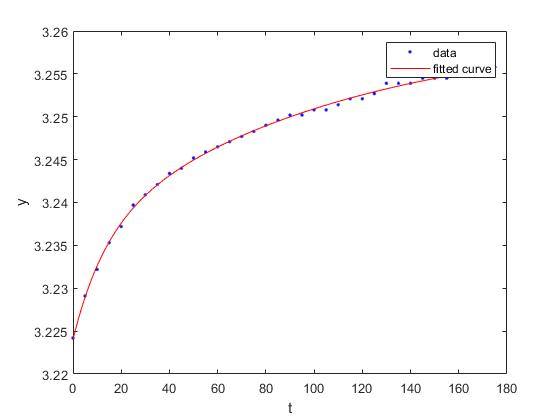

cfun =      General model:
     cfun(t) = a-b*exp(-c*t)-d*exp(-e*t)
     Coefficients (with 95% confidence bounds):
       a =       3.278  (3.267, 3.29)
       b =     0.02119  (0.01281, 0.02958)
       c =    0.005018  (-8.386e-05, 0.01012)
       d =     0.01529  (0.01205, 0.01853)
       e =     0.05317  (0.0412, 0.06514)

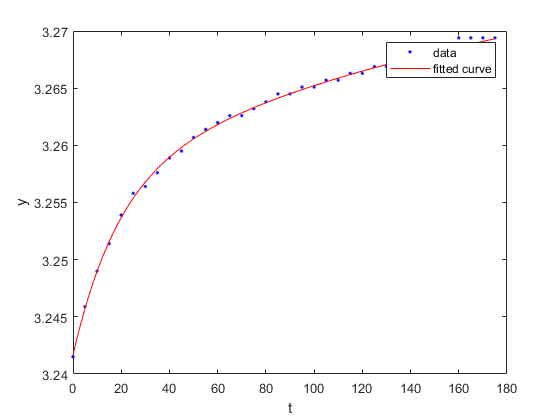

cfun =      General model:
     cfun(t) = a-b*exp(-c*t)-d*exp(-e*t)
     Coefficients (with 95% confidence bounds):
       a =       3.276  (3.275, 3.277)
       b =     0.01615  (0.01482, 0.01749)
       c =     0.01424  (0.0113, 0.01718)
       d =    0.008771  (0.006866, 0.01068)
       e =       0.095  (0.06852, 0.1215)

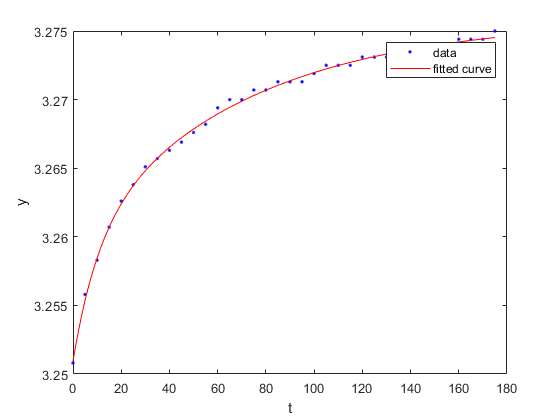

cfun =      General model:
     cfun(t) = a-b*exp(-c*t)-d*exp(-e*t)
     Coefficients (with 95% confidence bounds):
       a =       3.285  (3.283, 3.288)
       b =     0.01432  (0.01331, 0.01532)
       c =    0.009343  (0.004954, 0.01373)
       d =     0.01137  (0.008871, 0.01387)
       e =       0.067  (0.05067, 0.08334)

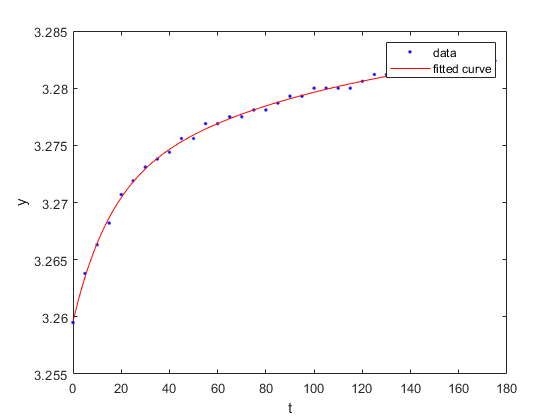

cfun =      General model:
     cfun(t) = a-b*exp(-c*t)-d*exp(-e*t)
     Coefficients (with 95% confidence bounds):
       a =        3.31  (3.306, 3.314)
       b =     0.02468  (0.02249, 0.02687)
       c =     0.00679  (0.004449, 0.00913)
       d =     0.01159  (0.00973, 0.01345)
       e =     0.06602  (0.05313, 0.0789)

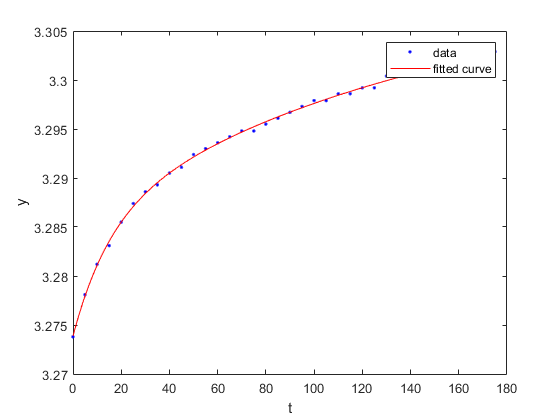

cfun =      General model:
     cfun(t) = a-b*exp(-c*t)-d*exp(-e*t)
     Coefficients (with 95% confidence bounds):
       a =       3.318  (3.316, 3.32)
       b =     0.01557  (0.01455, 0.01658)
       c =    0.009767  (0.005958, 0.01358)
       d =     0.01233  (0.009958, 0.01471)
       e =     0.06901  (0.05408, 0.08393)

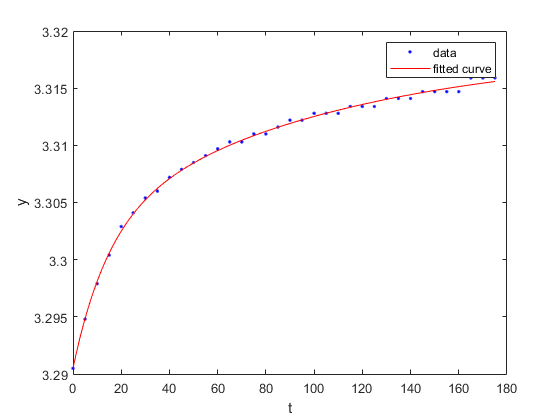

cfun =      General model:
     cfun(t) = a-b*exp(-c*t)-d*exp(-e*t)
     Coefficients (with 95% confidence bounds):
       a =        3.32  (3.319, 3.321)
       b =     0.01337  (0.01264, 0.01411)
       c =     0.01092  (0.007774, 0.01407)
       d =     0.00864  (0.007158, 0.01012)
       e =     0.09686  (0.0727, 0.121)

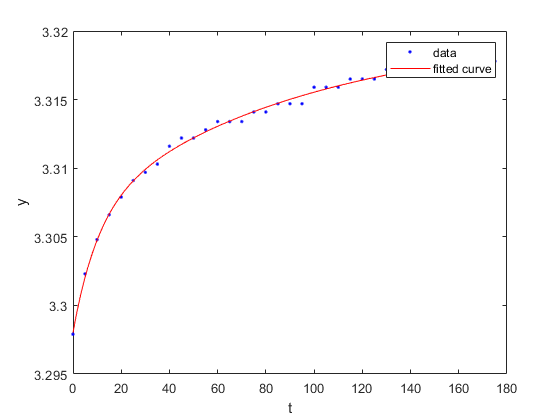

cfun =      General model:
     cfun(t) = a-b*exp(-c*t)-d*exp(-e*t)
     Coefficients (with 95% confidence bounds):
       a =       3.322  (3.321, 3.323)
       b =    0.009679  (0.007517, 0.01184)
       c =     0.01336  (0.00706, 0.01967)
       d =    0.008954  (0.006005, 0.0119)
       e =     0.06898  (0.04702, 0.09095)

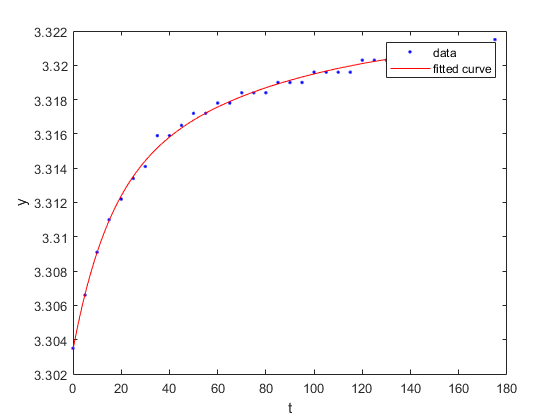

% 数据切片
dataseg_d = cell(11,5); % 用于保存原始数据 11个SOC，五个参数：Ut I Time refsoc Capacity

% 考虑剔除直流内阻 第一步即5s内为直流内阻
% for index =1:11 % 分别是95% 90% ... 5% index用于记录，需要和具体对应SOC换算（index+1/index+2）
%     dataseg_d{index,1} = Ut(CTR(index+1)+1 : RTC(index+2));    % 由于静置采样5s肯定大于R0fittime，所以数据直接加1个采样
%     dataseg_d{index,2} = I(CTR(index+1)+1 : RTC(index+2));     
%     dataseg_d{index,3} = Time(CTR(index+1)+1 : RTC(index+2));
%     dataseg_d{index,4} = refsoc(CTR(index+1)+1 : RTC(index+2));
%     dataseg_d{index,5} = Capacity(CTR(index+1)+1 : RTC(index+2));
% end

% 2021.12.21调试测试 认为回升过程的1采样剔除会导致 极化电压有误
% for index =1:11 % 分别是95% 90% ... 5% index用于记录，需要和具体对应SOC换算（index+1/index+2）
%     dataseg_d{index,1} = Ut(CTR(index+1) : RTC(index+2));    % 由于静置采样5s肯定大于R0fittime，所以数据直接加1个采样
%     dataseg_d{index,2} = I(CTR(index+1) : RTC(index+2));     
%     dataseg_d{index,3} = Time(CTR(index+1) : RTC(index+2));
%     dataseg_d{index,4} = refsoc(CTR(index+1) : RTC(index+2));
%     dataseg_d{index,5} = Capacity(CTR(index+1) : RTC(index+2));
% end

% 2021.12.21调试测试 静置回升拟合时间设定为30min
for index =1:11 % 分别是95% 90% ... 5% index用于记录，需要和具体对应SOC换算（index+1/index+2）
    dataseg_d{index,1} = Ut(CTR(index+1)+1 : CTR(index+1)+taufittime);    % 由于静置采样5s肯定大于R0fittime，所以数据直接加1个采样
    dataseg_d{index,2} = I(CTR(index+1)+1 : CTR(index+1)+taufittime);     % 选择共静置30min的数据进行拟合 30*60/5 = 360
    dataseg_d{index,3} = Time(CTR(index+1)+1 : CTR(index+1)+taufittime);
    dataseg_d{index,4} = refsoc(CTR(index+1)+1 : CTR(index+1)+taufittime);
    dataseg_d{index,5} = Capacity(CTR(index+1)+1 : CTR(index+1)+taufittime);
end

dataseg_d = flipud(dataseg_d); % 关键步骤，顺序调换为5% ... 90% 95% 与上文保持一致

for index = 1:11
    % 拟合参数构建
    x = dataseg_d{index,3} - dataseg_d{index,3}(1); % Time
    y = dataseg_d{index,1}; % Ut
    
    %% 一阶fit （受限于静置过长，单个RC环节在这种情况下很难找到能体现快和慢的RC参数）
    % syms t
    % f=fittype('a-b*exp(-c*t)','independent','t','coefficients',{'a','b','c'});  %fittype是自定义拟合函数
    % opt=fitoptions(f);
    % opt.StartPoint=[3 0.05 0.001];
    % cfun=fit(x , y , f, opt)
    % figure, plot(cfun,x,y);
    
    % 二阶fit（建议二阶剔除直流内阻，这样可以充分使用第一个RC环拟合短时间响应，第二个RC环拟合长时间响应）
    % （不剔除直流内阻的话，第一个RC环会拟合部分直流信息）
    [tau1,tau2,polarU1(index),polarU2(index)] = plusfitting_timeconstant_2RC_d(x,y);
    
    %% 三阶fit
    % syms t
    % f=fittype('a-b*exp(-c*t)-d*exp(-e*t)-f*exp(-g*t)','independent','t','coefficients',{'a','b','c','d','e','f','g'});  %fittype是自定义拟合函数
    % opt=fitoptions(f);
    % opt.StartPoint=[3 0.05 0.1 0.005 0.01 0.005 0.0005];
    % cfun=fit(x , y , f, opt)
    % figure, plot(cfun,x,y);
    % coe = coeffvalues(cfun);
    % tau1 = 1/coe(3);
    % tau2 = 1/coe(5);
    % tau3 = 1/coe(7);
    % polarU1 = coe(2);
    % polarU2 = coe(4);
    % polarU3 = coe(6);
    theta_d(3,index) = tau1; % 整理参数表
    theta_d(5,index) = tau2; % 整理参数表
end

## 极化内阻方法二 极化电压不变

clear dataseg_d;
dataseg_d = cell(11,5);

for index =1:11 % 分别是95% 90% ... 5% index用于记录，需要和具体对应SOC换算（index+2/index+2）
    dataseg_d{index,1} = Ut(RTC(index+2)+R0fittime : CTR(index+2));    % 认为R0fittime时刻之后的是极化效应
    dataseg_d{index,2} = I(RTC(index+2)+R0fittime : CTR(index+2));     % 从CTR到CTR+R0fittime之间是直流内阻
    dataseg_d{index,3} = Time(RTC(index+2)+R0fittime : CTR(index+2));
    dataseg_d{index,4} = refsoc(RTC(index+2)+R0fittime : CTR(index+2));
    dataseg_d{index,5} = Capacity(RTC(index+2)+R0fittime : CTR(index+2));
end

dataseg_d = flipud(dataseg_d); % 关键步骤，顺序调换为5% ... 90% 95% 与上文保持一致

for index = 1:11
    time = dataseg_d{index,3}(end) - dataseg_d{index,3}(1);
    theta_d(2,index) = polarU1(index)/dataseg_d{index,2}(end)/(1-exp(-time/theta_d(3,index)))
    theta_d(4,index) = polarU2(index)/dataseg_d{index,2}(end)/(1-exp(-time/theta_d(5,index)))
end

theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022         0         0         0         0         0         0         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
         0         0         0         0         0         0         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022         0         0         0         0         0         0         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031         0         0         0         0         0         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010         0         0         0         0         0         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031         0         0         0         0         0         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010         0         0         0         0         0         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018         0         0         0         0         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007         0         0         0         0         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018         0         0         0         0         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007         0         0         0         0         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014         0         0         0         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007         0         0         0         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014         0         0         0         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007         0         0         0         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014         0         0         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009         0         0         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014         0         0         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009         0         0         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013         0         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009    0.0005         0         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013         0         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009    0.0005         0         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013    0.0009         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009    0.0005    0.0007         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013    0.0009         0         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009    0.0005    0.0007         0         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013    0.0009    0.0008         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009    0.0005    0.0007    0.0007         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013    0.0009    0.0008         0         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009    0.0005    0.0007    0.0007         0         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013    0.0009    0.0008    0.0014         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009    0.0005    0.0007    0.0007    0.0007         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013    0.0009    0.0008    0.0014         0         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009    0.0005    0.0007    0.0007    0.0007         0         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013    0.0009    0.0008    0.0014    0.0009         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009    0.0005    0.0007    0.0007    0.0007    0.0005         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013    0.0009    0.0008    0.0014    0.0009         0         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009    0.0005    0.0007    0.0007    0.0007    0.0005         0
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013    0.0009    0.0008    0.0014    0.0009    0.0008         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009    0.0005    0.0007    0.0007    0.0007    0.0005    0.0005
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013    0.0009    0.0008    0.0014    0.0009    0.0008         0
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


theta_d =     0.0020    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0017    0.0016    0.0016    0.0016
    0.0022    0.0010    0.0007    0.0007    0.0009    0.0005    0.0007    0.0007    0.0007    0.0005    0.0005
   18.1547   10.5664   11.3266   13.2065   18.8082   10.5265   14.9245   15.1478   14.4911   10.3246   14.4964
    0.0031    0.0018    0.0014    0.0014    0.0013    0.0009    0.0008    0.0014    0.0009    0.0008    0.0006
  193.0043   66.1069   83.7018  104.5522  199.2753   70.2355  107.0313  147.2838  102.3834   91.5614   74.8333


## 充电部

% ***************************************************************************************************

## 时间常数

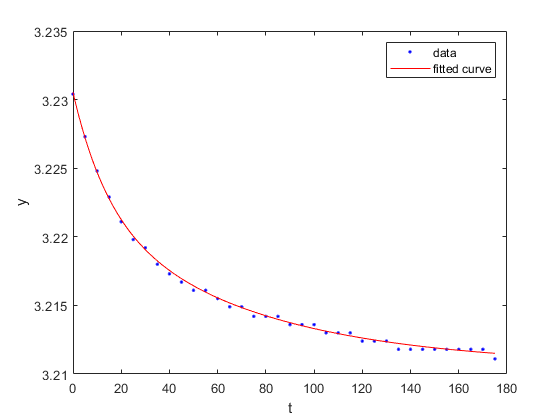

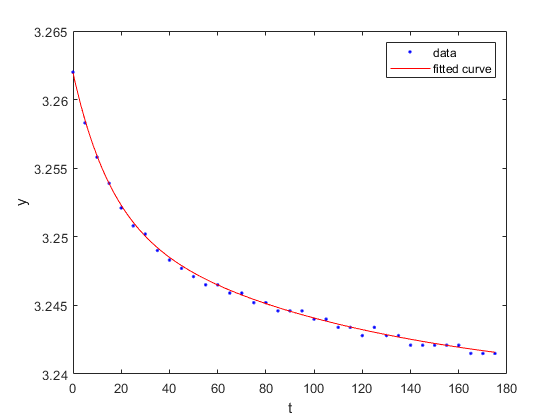

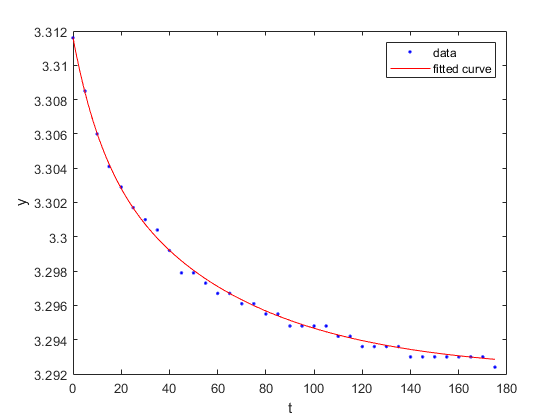

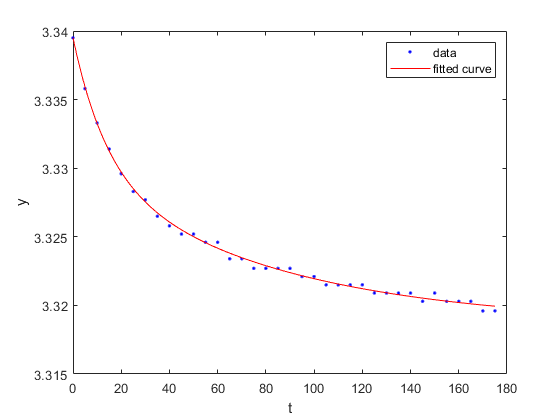

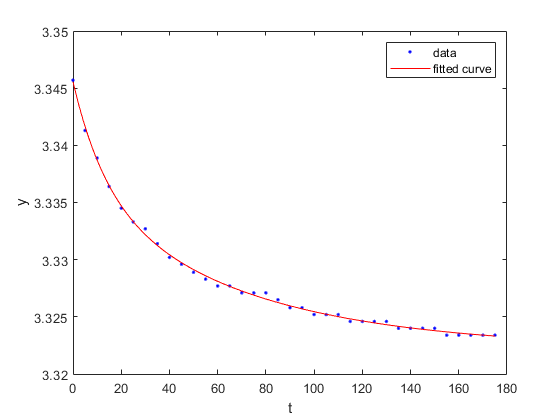

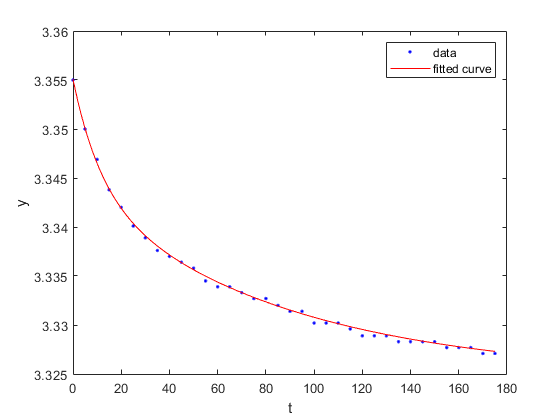

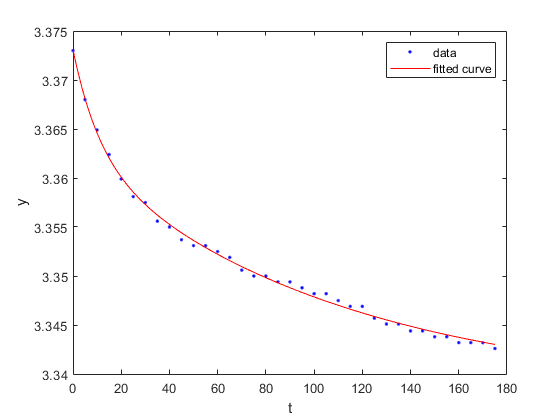

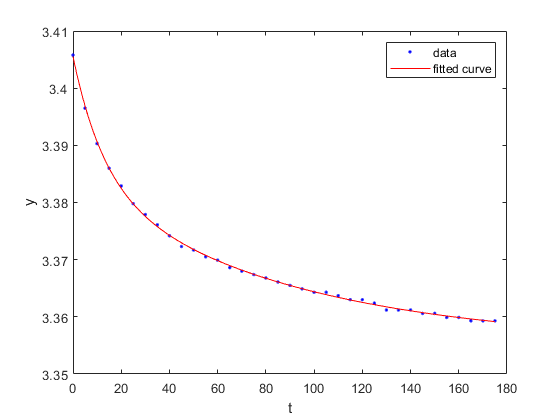

polarU1 = zeros(1,11);  % 复位
polarU2 = zeros(1,11);  % 复位
% 数据切片
dataseg_c = cell(11,5); % 用于保存原始数据 11个SOC，五个参数：Ut I Time refsoc Capacity

% 考虑剔除直流内阻 第一步即5s内为直流内阻
% for index = 1:11 % 分别是5%...90% 95% index用于记录，需要和具体对应SOC换算（index+13/index+14）
%     dataseg_c{index,1} = Ut(CTR(index+13)+1 : RTC(index+14));    % 由于静置采样5s肯定大于R0fittime，所以数据直接加1个采样
%     dataseg_c{index,2} = I(CTR(index+13)+1 : RTC(index+14));     
%     dataseg_c{index,3} = Time(CTR(index+13)+1 : RTC(index+14));
%     dataseg_c{index,4} = refsoc(CTR(index+13)+1 : RTC(index+14));
%     dataseg_c{index,5} = Capacity(CTR(index+13)+1 : RTC(index+14));
% end

% 2021.12.21调试测试 认为回升过程的1采样剔除会导致 极化电压有误
% for index = 1:11 % 分别是5%...90% 95% index用于记录，需要和具体对应SOC换算（index+13/index+14）
%     dataseg_c{index,1} = Ut(CTR(index+13) : RTC(index+14));    % 由于静置采样5s肯定大于R0fittime，所以数据直接加1个采样
%     dataseg_c{index,2} = I(CTR(index+13) : RTC(index+14));     
%     dataseg_c{index,3} = Time(CTR(index+13) : RTC(index+14));
%     dataseg_c{index,4} = refsoc(CTR(index+13) : RTC(index+14));
%     dataseg_c{index,5} = Capacity(CTR(index+13) : RTC(index+14));
% end

% 2021.12.21调试测试 静置回升拟合时间设定为30min
for index =1:11 % 分别是95% 90% ... 5% index用于记录，需要和具体对应SOC换算（index+1/index+2）
    dataseg_c{index,1} = Ut(CTR(index+13)+1 : CTR(index+13)+taufittime);    % 由于静置采样5s肯定大于R0fittime，所以数据直接加1个采样
    dataseg_c{index,2} = I(CTR(index+13)+1 : CTR(index+13)+taufittime);     % 选择共静置30min的数据进行拟合 30*60/5 = 360
    dataseg_c{index,3} = Time(CTR(index+13)+1 : CTR(index+13)+taufittime);
    dataseg_c{index,4} = refsoc(CTR(index+13)+1 : CTR(index+13)+taufittime);
    dataseg_c{index,5} = Capacity(CTR(index+13)+1 : CTR(index+13)+taufittime);
end

for index = 1:11
    % 拟合参数构建
    x = dataseg_c{index,3} - dataseg_c{index,3}(1); % Time
    y = dataseg_c{index,1}; % Ut
    
    %% 一阶fit （受限于静置过长，单个RC环节在这种情况下很难找到能体现快和慢的RC参数）
    % syms t
    % f=fittype('a-b*exp(-c*t)','independent','t','coefficients',{'a','b','c'});  %fittype是自定义拟合函数
    % opt=fitoptions(f);
    % opt.StartPoint=[3 0.05 0.001];
    % cfun=fit(x , y , f, opt)
    % figure, plot(cfun,x,y);
    
    % 二阶fit（建议二阶剔除直流内阻，这样可以充分使用第一个RC环拟合短时间响应，第二个RC环拟合长时间响应）
    % （不剔除直流内阻的话，第一个RC环会拟合部分直流信息）
    [tau1,tau2,polarU1(index),polarU2(index)] = plusfitting_timeconstant_2RC_c(x,y);
    
    %% 三阶fit
    % syms t
    % f=fittype('a-b*exp(-c*t)-d*exp(-e*t)-f*exp(-g*t)','independent','t','coefficients',{'a','b','c','d','e','f','g'});  %fittype是自定义拟合函数
    % opt=fitoptions(f);
    % opt.StartPoint=[3 0.05 0.1 0.005 0.01 0.005 0.0005];
    % cfun=fit(x , y , f, opt)
    % figure, plot(cfun,x,y);
    % coe = coeffvalues(cfun);
    % tau1 = 1/coe(3);
    % tau2 = 1/coe(5);
    % tau3 = 1/coe(7);
    % polarU1 = coe(2);
    % polarU2 = coe(4);
    % polarU3 = coe(6);
    theta_c(3,index) = tau1; % 整理参数表
    theta_c(5,index) = tau2; % 整理参数表
end

## 极化内阻方法二 极化电压不变

clear dataseg_d;
dataseg_c = cell(11,5);

for index =1:11 % 分别是5%...90% 95% index用于记录，需要和具体对应SOC换算（index+14/index+14）
    dataseg_c{index,1} = Ut(RTC(index+2)+R0fittime : CTR(index+2));    % 认为R0fittime时刻之后的是极化效应
    dataseg_c{index,2} = I(RTC(index+2)+R0fittime : CTR(index+2));     % 从CTR到CTR+R0fittime之间是直流内阻
    dataseg_c{index,3} = Time(RTC(index+2)+R0fittime : CTR(index+2));
    dataseg_c{index,4} = refsoc(RTC(index+2)+R0fittime : CTR(index+2));
    dataseg_c{index,5} = Capacity(RTC(index+2)+R0fittime : CTR(index+2));
end

for index = 1:11
    time = dataseg_c{index,3}(end) - dataseg_c{index,3}(1);
    theta_c(2,index) = polarU1(index)/dataseg_c{index,2}(end)/(1-exp(-time/theta_c(3,index)))
    theta_c(4,index) = polarU2(index)/dataseg_c{index,2}(end)/(1-exp(-time/theta_c(5,index)))
end

theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005         0         0         0         0         0         0         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
         0         0         0         0         0         0         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005         0         0         0         0         0         0         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007         0         0         0         0         0         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006         0         0         0         0         0         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007         0         0         0         0         0         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006         0         0         0         0         0         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007         0         0         0         0         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003         0         0         0         0         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007         0         0         0         0         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003         0         0         0         0         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008         0         0         0         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006         0         0         0         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008         0         0         0         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006         0         0         0         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007         0         0         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005         0         0         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007         0         0         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005         0         0         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008         0         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005    0.0006         0         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008         0         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005    0.0006         0         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008    0.0011         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005    0.0006    0.0006         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008    0.0011         0         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005    0.0006    0.0006         0         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008    0.0011    0.0014         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005    0.0006    0.0006    0.0007         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008    0.0011    0.0014         0         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005    0.0006    0.0006    0.0007         0         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008    0.0011    0.0014    0.0010         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005    0.0006    0.0006    0.0007    0.0010         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008    0.0011    0.0014    0.0010         0         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005    0.0006    0.0006    0.0007    0.0010         0         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008    0.0011    0.0014    0.0010    0.0012         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005    0.0006    0.0006    0.0007    0.0010    0.0013         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008    0.0011    0.0014    0.0010    0.0012         0         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005    0.0006    0.0006    0.0007    0.0010    0.0013         0
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008    0.0011    0.0014    0.0010    0.0012    0.0017         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005    0.0006    0.0006    0.0007    0.0010    0.0013    0.0017
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008    0.0011    0.0014    0.0010    0.0012    0.0017         0
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


theta_c =     0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0005    0.0006    0.0003    0.0006    0.0005    0.0006    0.0006    0.0007    0.0010    0.0013    0.0017
   14.0377   15.2996   11.4723   13.7298   13.4816   11.4887   10.9373    9.9985   12.0054   12.7672   11.1831
    0.0007    0.0007    0.0008    0.0007    0.0008    0.0011    0.0014    0.0010    0.0012    0.0017    0.0021
   68.9563  107.9283   59.9466   81.4543   68.1759   85.9968  109.4603   92.3480  104.8463   87.3518   66.2257


## 绘图

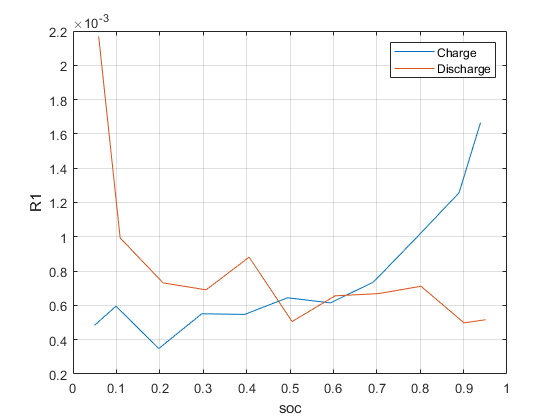

figure, plot(soctable_c,theta_c(2,:)),hold on ,plot(soctable_d,theta_d(2,:));
grid on
xlabel('soc'), ylabel('R1');
legend('Charge','Discharge');

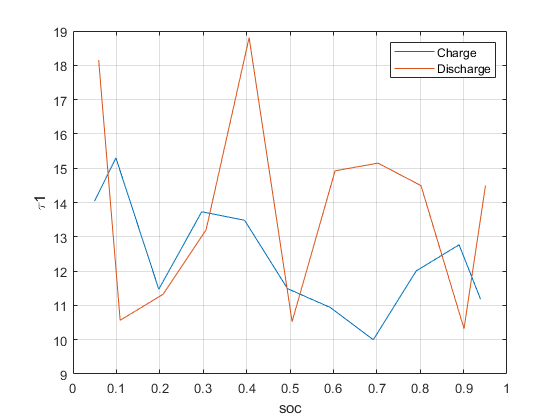


figure, plot(soctable_c,theta_c(3,:)),hold on ,plot(soctable_d,theta_d(3,:));
grid on
xlabel('soc'), ylabel('\tau1');
legend('Charge','Discharge');

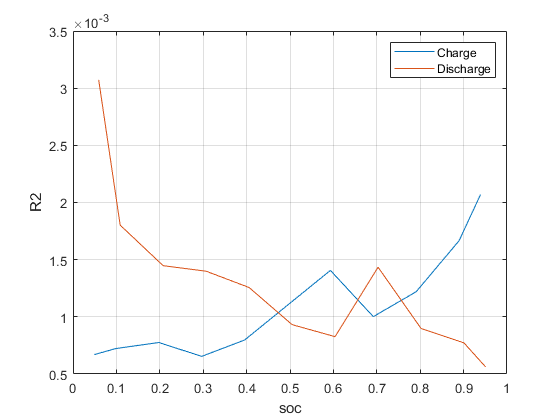


figure, plot(soctable_c,theta_c(4,:)),hold on ,plot(soctable_d,theta_d(4,:));
grid on
xlabel('soc'), ylabel('R2');
legend('Charge','Discharge');

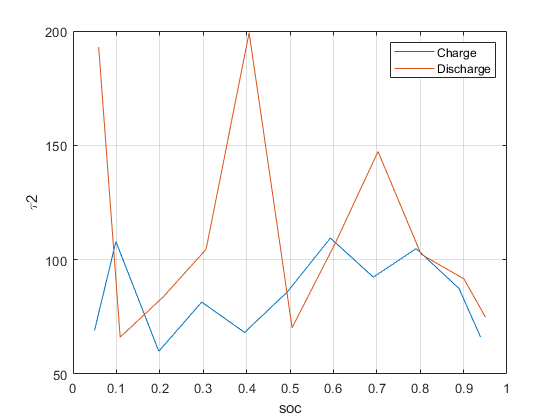


figure, plot(soctable_c,theta_c(5,:)),hold on ,plot(soctable_d,theta_d(5,:));
grid on
xlabel('soc'), ylabel('\tau2');
legend('Charge','Discharge');

## 极化内阻方法一 再拟合

% 方法<1>：拟合
% clear dataseg_d;
% 
% for index =1:11 % 分别是95% 90% ... 5% index用于记录，需要和具体对应SOC换算（index+1/index+2）
%     dataseg_d{index,1} = Ut(RTC(index+2)+R0fittime : CTR(index+2));    % 认为R0fittime时刻之后的是极化效应
%     dataseg_d{index,2} = I(RTC(index+2)+R0fittime : CTR(index+2));     % 从CTR到CTR+R0fittime之间是直流内阻
%     dataseg_d{index,3} = Time(RTC(index+2)+R0fittime : CTR(index+2));
%     dataseg_d{index,4} = refsoc(RTC(index+2)+R0fittime : CTR(index+2));
%     dataseg_d{index,5} = Capacity(RTC(index+2)+R0fittime : CTR(index+2));
% end
% 
% index = 1;
% fitdataseg_d{index,3} = dataseg_d{index,3} - dataseg_d{index,3}(1); % Time
% fitdataseg_d{index,1} = interp1([refsoc(RTC(3)),refsoc(RTC(4))],[Ut(RTC(3)),Ut(RTC(4))],dataseg_d{index,4}) - dataseg_d{index,2} .* interp1(R0_dtable,R0_d,dataseg_d{index,4}) - dataseg_d{index,1} ; % OCV-IR0-Ut
% fitdataseg_d{index,1} = fitdataseg_d{index,1}./dataseg_d{index,2}; % (OCV-IR0-Ut)/I
% 
% for ii = 1:length(fitdataseg_d{index,1}) % 纠正小于0误差
%     if fitdataseg_d{index,1}(ii)<0
%         fitdataseg_d{index,1}(ii) = 0;
%     end
% end
% 
% x = fitdataseg_d{index,3};
% y = fitdataseg_d{index,1};

% 二阶
% syms t
% f=fittype('b*(1-exp(-t/tau1))+c*(1-exp(-t/tau2))','independent','t','coefficients',{'b','c'},'problem',{'tau1','tau2'});  %fittype是自定义拟合函数
% opt=fitoptions(f);
% opt.StartPoint=[0.00085,0.0051];
% opt.Lower = [0.00083,0.0049];
% opt.Upper = [0.00086,0.0052];
% opt.StartPoint=[0.00085,0.0051];
% opt.Lower = [0,0];
% opt.Upper = [0.01,0.01];
% cfunn=fit(x , y , f, 'problem',{tau1,tau2},opt)
% 
% figure, plot(cfunn,x,y);

% 三阶
% syms t
% f=fittype('b*(1-exp(-t/tau1))+c*(1-exp(-t/tau2))+d*(1-exp(-t/tau3))','independent','t','coefficients',{'b','c','d'},'problem',{'tau1','tau2','tau3'});  %fittype是自定义拟合函数
% opt=fitoptions(f);
% opt.StartPoint=[0.001,0.001,0.001];
% opt.Lower = [0,0,0];
% opt.Upper = [0.1,0.1,0.1];
% cfunn=fit(x , y , f, 'problem',{tau1,tau2,tau3},opt)
% 
% figure, plot(cfunn,x,y);


## 命名修改

theta_d1 = zeros(5,11);
theta_c1 = zeros(5,11);

theta_d1(:,2:10) = theta_d(:,2:10);
theta_d1(:,1) = theta_d(:,2);
theta_d1(:,11) = theta_d(:,10);

theta_c1(:,2:10) = theta_c(:,2:10);
theta_c1(:,1) = theta_c(:,2);
theta_c1(:,11) = theta_c(:,10);

theta_d = theta_d1;
theta_c = theta_c1;
